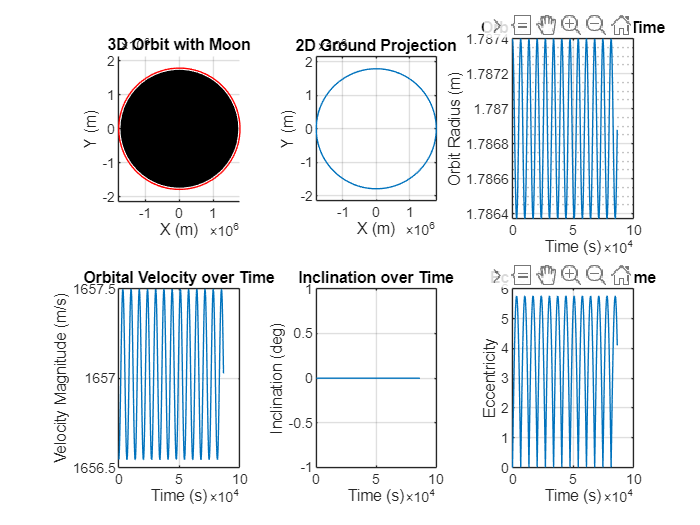

lunar_orbit_simulation()

function lunar_orbit_simulation()
    % Fysiske konstanter
    mu_moon = 4.9048695e12; % Gravitational parameter for the Moon (m^3/s^2)
    R_moon = 1737.4e3; % Radius of the Moon (m)
    J2 = 2.032e-4; % J2 coefficient for the Moon
    AU = 1.496e11; % Astronomical unit (m)
    c = 299792458; % Speed of light (m/s)
    P_sun = 4.57e-6; % Solar radiation pressure (N/m^2)
    A_m = 1; % Satellite area-to-mass ratio (m^2/kg)
    
    % Initial conditions
    altitude = 50e3; % Altitude (m)
    r0 = R_moon + altitude; % Initial radial distance (m)
    v0 = sqrt(mu_moon / r0); % Circular orbit velocity (m/s)
    state0 = [r0; 0; 0; 0; v0; 0]; % Initial state [x, y, z, vx, vy, vz]
    
    % Simuleringstid
    tspan = [0, 24*3600]; % One day in seconds
    
    % Integrasjon
    options = odeset('RelTol', 1e-9, 'AbsTol', 1e-9);
    [t, state] = ode45(@(t, s) orbit_dynamics(t, s, mu_moon, R_moon, J2, P_sun, A_m, AU, c), tspan, state0, options);
    
    % Beregn orbitalparametere
    [inclination, eccentricity] = compute_orbital_elements(state, mu_moon);
    
    % Plot resultater
    figure;
    subplot(2,3,1);
    hold on;
    [X, Y, Z] = sphere(50);
    surf(R_moon*X, R_moon*Y, R_moon*Z, 'FaceColor', 'k', 'EdgeColor', 'none');
    plot3(state(:,1), state(:,2), state(:,3), 'r');
    xlabel('X (m)'); ylabel('Y (m)'); zlabel('Z (m)');
    title('3D Orbit with Moon');
    grid on;
    axis equal;
    hold off;
    
    subplot(2,3,2);
    plot(state(:,1), state(:,2));
    xlabel('X (m)'); ylabel('Y (m)');
    title('2D Ground Projection');
    grid on;
    axis equal;
    
    subplot(2,3,3);
    semilogy(t, vecnorm(state(:,1:3), 2, 2));
    xlabel('Time (s)'); ylabel('Orbit Radius (m)');
    title('Orbital Radius over Time');
    grid on;
    
    subplot(2,3,4);
    plot(t, vecnorm(state(:,4:6), 2, 2));
    xlabel('Time (s)'); ylabel('Velocity Magnitude (m/s)');
    title('Orbital Velocity over Time');
    grid on;
    
    subplot(2,3,5);
    plot(t, inclination);
    xlabel('Time (s)'); ylabel('Inclination (deg)');
    title('Inclination over Time');
    grid on;
    
    subplot(2,3,6);
    plot(t, eccentricity);
    xlabel('Time (s)'); ylabel('Eccentricity');
    title('Eccentricity over Time');
    grid on;
end

function [inclination, eccentricity] = compute_orbital_elements(state, mu)
    h = cross(state(:,1:3), state(:,4:6));
    inclination = acosd(h(:,3) ./ vecnorm(h, 2, 2));
    r_norm = vecnorm(state(:,1:3), 2, 2);
    v_norm = vecnorm(state(:,4:6), 2, 2);
    energy = 0.5 * v_norm.^2 - mu ./ r_norm;
    a = -mu ./ (2 * energy);
    eccentricity = sqrt(1 - vecnorm(h, 2, 2).^2 ./ (mu * a));
end

function dsdt = orbit_dynamics(~, s, mu, R, J2, P_sun, A_m, AU, c)
    r = s(1:3);
    v = s(4:6);
    r_norm = norm(r);
    
    % Gravitational acceleration
    acc_gravity = -mu * r / r_norm^3;
    
    % J2 Perturbation
    z2 = r(3)^2;
    factor = 1.5 * J2 * (mu / r_norm^2) * (R / r_norm)^2;
    acc_J2 = factor * [(r(1)/r_norm) * (5*z2/r_norm^2 - 1);
                       (r(2)/r_norm) * (5*z2/r_norm^2 - 1);
                       (r(3)/r_norm) * (5*z2/r_norm^2 - 3)];
    
    % Solar Radiation Pressure (assuming sun in +X direction)
    sun_vector = [AU; 0; 0];
    sun_dist = norm(sun_vector - r);
    acc_srp = P_sun * A_m / c * (sun_vector - r) / sun_dist;
    
    % Total acceleration
    acc_total = acc_gravity + acc_J2 + acc_srp;
    
    % State derivative
    dsdt = [v; acc_total];
end